# DoE Generator Live Script

## Create structure listing identification parameters

The Fouling Model Simulation Code is supplied with 3 structures which configure the model for each simulation run:

- ***BoundCond***: supplies the boundary conditions for the simulation.

- ***ModelPara***: defines the identification parameter settings for the current simulation.

- ***Options***: enables or disables the soot deposit and removal mechanisms and the HC and water condensation and evaporiasation models.

Note, distributed parameters are represented as B-splines for compactness and are automatically converted to lookup tables by the code. By convention, it is assumed the lookup contains the axial distance data in the first row! This convention ensures consistency.

clear;
clc;

F(1).Name = "k_d";                  % Deposit thermal conductivity
F(1).Units = "[W/m/K]";
F(1).Fixed = false;                 % Distributed parameter
F(1).Lo = 0.02;   
F(1).Hi = 0.25;
F(1).Sz = [2, 11];
F(1).Type = "Parameter";
F(2).Name = "rho_d";                % Deposit density
F(2).Units = "[kg/m^3]";
F(2).Fixed = false;                 % Distributed parameter
F(2).Lo = 5;
F(2).Hi = 60;
F(2).Sz = [2, 11];
F(2).Type = "Parameter";
F(3).Name = "soot_phi0";
F(3).Units = "[m]";
F(3).Fixed = false;                 % Distributed parameter
F(3).Lo = 0.00001;
F(3).Hi = 0.0005;
F(3).Sz = [2, 11];
F(3).Type = "Boundary";
F(4).Name = "Ks";                   % Particle sticking probability gain
F(4).Units = "";
F(4).Fixed = true;                  % Fixed parameter
F(4).Lo = 0.100;
F(4).Hi = 0.900;
F(4).Sz = [1,1];                    % Size must be [1,1] for scalar parameter
F(4).Type = "Parameter";
% F(6).Name = "fRegMP";               % Friction factor regression parameters
% F(6).Units = "[]";
% F(6).Fixed = true;                  % Fixed parameter
% F(6).Lo = [ 0 -0.5; 0.001 -0.3; 0.1 -0.1 ];
% F(6).Hi = [ 0.25 -0.01; 0.1 -0.01; 150 0.1];
% F(6).Sz = [3,2];
% F(6).Type = "Parameter";
% F(7).Name = "K";                    % Shear stress removal mechanism gain
% F(7).Units = "";
% F(7).Fixed = true;                  % Fixed parameter
% F(7).Lo = 0.01;
% F(7).Hi = 0.3;
% F(7).Sz = [1,1]; 
% F(7).Type = "Parameter";
% F(4).Name = "K_HCs";                % HC condensation/evaporation gain
% F(4).Units = "";
% F(4).Fixed = true;                  % Fixed parameter
% F(4).Lo = 0.00001;
% F(4).Hi = 0.0050;
% F(4).Sz = [1,1]; 
% F(4).Type = "Parameter";
% F(4).Name = "NuRegMP";              % Nusselt number regression parameters
% F(4).Units = "";
% F(4).Fixed = true;                  % Fixed parameter
% F(4).Lo = 0.0001;
% F(4).Hi = 1;
% F(4).Sz = [1,3]; 
% F(4).Type = "Parameter";

## Enable/Disable Derivative B-Spline Constraints

***Con*** is a multi-dimensional structure specifiying the necessary constraints. The structure must have the fields:

Name              -->  parameter or boundary condition name

derivative        --> set to 0,1 or 2 {0} to specify the spline derivative to which the constraint applies.

type                --> set to '==','>=' or '<='

value             --> constraint bound value

x                    --> Axial coordinates at which constraints apply. Leave empty to specify all training x-ordinates

For example, imagine we require to constrain the second derivative of the initial deposit layer thickness (soot_phi0) to be greater or equal to zero everywhere. Then set:

Con(1).name = 'soot_phi0';

Con(1).derivative = 2;

Con(1).type = '>=';

Con(1).value = 0;

Con(1).x = [];

ConstraintsEnable = true;
if ConstraintsEnable
    % Constrain the second derivative of the initial deposit layer thickness >= 0
    Con(1).name = 'soot_phi0';                                                          %#ok<*UNRCH> 
    Con(1).derivative = 2;
    Con(1).type = '>=';
    Con(1).value = 0;
    Con(1).x = [];
else
    % disable constraints - do not edit this!!!!!
    Con = struct.empty;
end

## Create Sobol Sequence object and generate experiment

Sobj = SobolSequence( F, Con, "M", 3, "K", 1 );                   % Quadratic B-spline with 1 knots for distributed parameters
%-----------------------------------------------------------------
% Design size is user selectable and sequence should be scrambled.
%-----------------------------------------------------------------
DesignSize = 701;
Sobj = Sobj.generate( DesignSize, "Scramble", true );

## Generate the DoEhook object connecting the BO and ECOMO model objects

H = DoEhook();
H = H.addDesignAvailableListener( Sobj );   % Add listener for the design available event
Sobj.export();                              % Generate the parameter table

## Generate the ECOMO interface object & run the experiment. Create the Bayesian optimisation object at the end of the simulation runs.

E = ecomoInterface();
%-----------------------------------------------------------------------
% Define name of variable to load
%-----------------------------------------------------------------------
StructName = "EGRVars";
E = E.loadIdentificationData( "", StructName );
E = E.addRunExperimentListener( H );
tic;
H.runSimulation();

-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object

toc;

Elapsed time is 1979.611052 seconds.


## Generate diagnostic plots

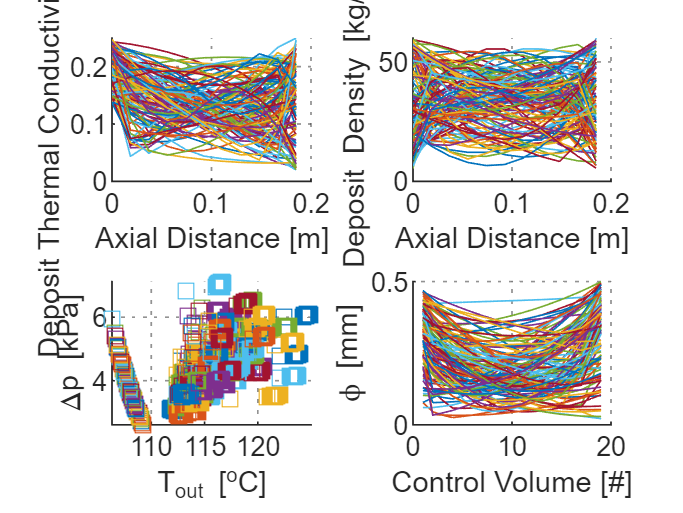

N = Sobj.NumPoints;
figure;
for Q = 1:4
    Ax( Q ) = subplot(2,2,Q);  %#ok<*SAGROW> 
    Ax( Q ).NextPlot = "add";
    grid on;
    Ax( Q ).GridAlpha = 0.5;
    Ax( Q ).GridLineStyle = ":";
end
for Q = 1:N
    plot( Ax( 1 ), E.FM(Q).ModelPara.k_d(:,1), E.FM(Q).ModelPara.k_d(:,2), '-' );     % Thermal conductivity
    plot( Ax( 2 ), E.FM(Q).ModelPara.rho_d(:,1), E.FM(Q).ModelPara.rho_d(:,2), '-');  % Deposit density
    plot( Ax( 3 ), E.FM(Q).T_out_L_degC, E.FM(Q).deltaPre_L_kPa, 's' );               % Temperature out versus delta pressure
    plot( Ax( 4 ), 1000 * E.FM( Q ).phi_soot_tn1, '-' );                              % Deposit thickness
end
xlabel( Ax( 1 ), "Axial Distance [m]");
ylabel( Ax( 1 ), "Deposit Thermal Conductivity [W/K/m]");
xlabel( Ax( 2 ), "Axial Distance [m]");
ylabel( Ax( 2 ), "Deposit Density [kg/m^3]");
xlabel( Ax( 3 ), "T_{out} [^oC]");
ylabel( Ax( 3 ), "\Deltap [kPa]")
xlabel( Ax( 4 ), "Control Volume [#]");
ylabel( Ax( 4 ), "\phi [mm]");

## Minimise the BO Acquisition Function & Update the Training Data

DataBudget = 20;
ConvCounterLimit = 2;
if ( H.Uh == 0 )
    H = H.addProcessNewQueryListener( E );      % Add the necessary listener
end
tic;
if isempty( E.B.Xnext )
    Xlast = E.B.Xbest;
end
Q = 0;
ConvFlg = false;
ConvCounter = 0;

while ( ~ConvFlg )
    Q = Q + 1;                              % data budget counter
    E = E.genNewQuery();                    % Solve the Bayesian optimisation acquisition function
    E.exportNewQuery();                     % Update the training data
    ConvCriteria = abs( ( E.B.Xnext - Xlast )./Xlast );
    if ( Q >= DataBudget )
        ConvFlg = true;
    elseif all( ConvCriteria < 0.00001 ) && ( ConvCounter >= ConvCounterLimit )
        ConvFlg = true;
    elseif all( ConvCriteria < 0.00001 )
        ConvCounter = ConvCounter + 1;
    end
    Xlast = E.B.Xnext;
end
toc;

## Plot the final "best" result from the Bayesian Optimisation Process

% Plot the best simulation results
E.plotBestSimulation();

## Time Series Plots

E.plotTimeSeries();

## Output Simulation Parameters to the Workspace

[ FMbest, ModelPara, BoundCond, Options ] = E.exportParameters();